# **Component master.**

***This is a compendium of a variety of formulas and calculations in regads to but not limiting: elecrical komponents, filters, measurements and effects.***

***Made by me during my engineering degree.***

***This is meant to be open for all whom would need it, expansion and contributions are welcomed, if so, and done cleanly and well documented. pleas push request the repository.***

**copr. 2021 Sverre Kvist. All rights reserved**

***Contributors:***

# Basic component calculations.

## Resistor in paralell. $R_{\textrm{total}} =\sum_1^n {\left(\frac{1}{R_n }\right)}^{-1}$

can also be used to calculate capacitance in capacitors coupeled in series and as is for inductors.

clc, clear, close all;
 

prompt = {'Resistors in paralell:'};
dlgtitle = 'Number of resistors';
dims = [1 35];
definput = {'1'};
Resistors = inputdlg(prompt,dlgtitle,dims,definput);
R_array = zeros(1,str2double(Resistors(1)));

for i=1:numel(R_array)
    temparr{i} = "Resistor";
end
x = inputdlg(temparr);
sum = 0;
for i=1:numel(x)
    sum = sum + (1/str2double(x{i}));
end
R_total = sum^-1

R_total = 1

## Resistor in Series. $R_{\textrm{total}} =\sum_1^n R_n$

Kan also be used to calculate capacitance in capacitors coupeled in paralell and as is for inductors.

clc, clear, close all;
 

prompt = {'Resistors in Series:'};
dlgtitle = 'Number of resistors';
dims = [1 35];
definput = {'1'};
Resistors = inputdlg(prompt,dlgtitle,dims,definput);
R_array = zeros(1,str2double(Resistors(1)));

for i=1:numel(R_array)
    temparr{i} = "Resistor";
end
x = inputdlg(temparr);
sum = 0;
for i=1:numel(x)
    sum = sum + (str2double(x{i}));
end
R_total = sum

R_total = 6

## Voltage-divider. $V_n =\frac{V_{\textrm{cc}} }{R_{\textrm{total}} }\cdot R_n \;$

clc, clear, close all;
V_CC = 18; R_n = 22000; R_total = 1;
V_n = (V_CC/R_total)*R_n

V_n = 396000

## Curent-divider. $I_n =\frac{I}{R_n }\cdot R_{\textrm{total}}$

clc, clear, close all;
I = 1; R_n = 1; R_total = 1;
I_n = (R_total/R_n)*I

# NTC-transistor.

## Calculate temperature. $T{\left[℃\right]}=\frac{\beta }{\ln {\left(\frac{R_T }{K}\right)}}-273\ldotp 15$

$\textrm{𝛽}=kelvin\ldotp \ \ \ \ \ \ \ \ \ \ R_T =Resistanse\ ved\ gitt\ temp\ldotp$       $K=\textrm{konstant}$.

clc, clear, close all;
syms T;
b = 3518; R = 1889;K = 0.0154; %Konstant
 
likn1=T==(b/log(R/K))-273.15;
temp = solve(likn1,T);
T=double(temp)

T = 27.0926

## Temp. at characreristic time. $T\left(t_c \right)\left\lbrack ℃\right\rbrack =T_a +\left(T_0 -T_a \right)e^{-t_{c/t_c } }$


$$e^{-t_{c/t_c } } =e^{-1} =0\ldotp 368$$


clc, clear, close all;
syms T(t_c)
T_0 =  1; T_a =  1;
e = 0.368;
T_c = T(t_c) == T_a*(T_a - T_0)*e

$$T\_c = T\left(t_{c}\right)=0$$

## Resistance at given temperature. $R_T {\left[\Omega \right]}=Ke^{\frac{\textrm{𝛽}}{T+273\ldotp 15}}$


$$\beta =\mathrm{kelvin}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;T=\mathrm{Given}\;\mathrm{temperature}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;K=\mathrm{Constant}\ldotp$$


clc, clear, close all;
syms R;
b = 3518;T =20;K =0.007275;
 
likn=R==K*exp(b/(T+273.15));
res = solve(likn,R);
RT=double(res)

RT = 1.1848e+03

# Wheatstone bridge.


$$V_{a\;} \left\lbrack V\right\rbrack =\frac{R}{R_1 +R}\cdot V_{s\;}$$
               
$$V_{b\;} \left\lbrack V\right\rbrack =\frac{R_3 }{\;R_2 +R_{3\;} }\cdot V_s$$



$$R_1 ,R_2 ,R_3 \left\lbrack \Omega \;\right\rbrack =F\mathrm{ixed}\;\mathrm{resistors}\ldotp \;\;\;\;\;\;\;\;V_s \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{source}\;\mathrm{voltage}\ldotp \;\;\;\;\;\;R\left\lbrack \Omega \;\right\rbrack =\mathrm{variable}\;\mathrm{resistor}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Delta \;V\left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Voltage}\;\mathrm{over}\;\mathrm{wheatstone}\;\mathrm{bridge}\ldotp$$


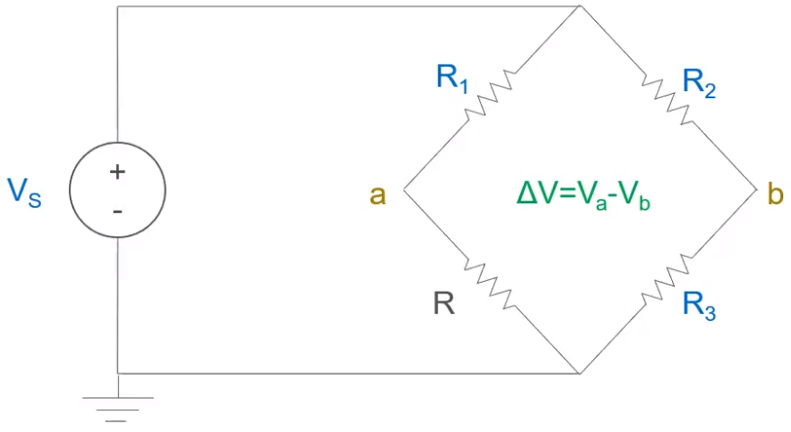

## Voltage diference. $\Delta V\left\lbrack V\right\rbrack =V_a -V_b =\left(\frac{R}{R_1 +R}-\frac{R_3 }{R_{2\;} +R_3 }\right)\cdot V_s$


$$R_1 ,R_2 ,R_3 \left\lbrack \Omega \;\right\rbrack =F\mathrm{ixed}\;\mathrm{resistors}\ldotp \;\;\;\;\;\;\;\;V_s \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{source}\;\mathrm{voltage}\ldotp \;\;\;\;\;\;R\left\lbrack \Omega \;\right\rbrack =\mathrm{variable}\;\mathrm{resistor}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Delta \;V\left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Voltage}\;\mathrm{over}\;\mathrm{wheatstone}\;\mathrm{bridge}\ldotp$$


clc, clear, close all;
Vs = 2.5;R1 = 120;R2 = 120;R3 = 120;      
R =124.8;           
 
Spenningsforskjell = ((R/(R1+R))-(R3/(R2+R3)))*Vs

Spenningsforskjell = 0.0245

## Resistance. $R\left\lbrack \Omega \;\right\rbrack =R_1 \cdot \frac{R_2 \Delta V+R_3 \left(V_s +\Delta V\right)}{R_2 \left(V_s -\Delta V\right)-R_3 \Delta V}$


$$R_1 ,R_2 ,R_3 \left\lbrack \Omega \;\right\rbrack =F\mathrm{ixed}\;\mathrm{resistors}\ldotp \;\;\;\;\;\;\;\;V_s \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{source}\;\mathrm{voltage}\ldotp \;\;\;\;\;\;R\left\lbrack \Omega \;\right\rbrack =\mathrm{variable}\;\mathrm{resistor}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Delta \;V\left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Voltage}\;\mathrm{over}\;\mathrm{wheatstone}\;\mathrm{bridge}\ldotp$$


clc, clear, close all;
R1 = 120;R2 = 120;R3 = 120;Vs = 2.5;
DeltaV = 22e-3;
 
R = (R1*(((R2*DeltaV)+R3*(Vs+DeltaV)))/(R2*(Vs-DeltaV)-R3*DeltaV))

R = 124.2997

# Operational amplifiers i.e. Op-Amp.

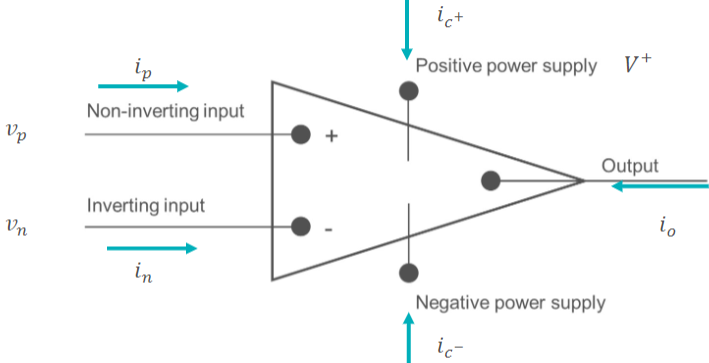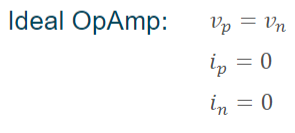

## inverting amplifier. $v_0 \left\lbrack V\right\rbrack =-\frac{R_f }{R_s }\cdot v_s$


$$v_0 \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Output}\;\mathrm{voltage}\ldotp \;\;\;\;\;\;\;v_s \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Source}\;\mathrm{voltage}\;\;\;\;\;\;\;\;\;\;R_f \left\lbrack \Omega \;\right\rbrack =\mathrm{Reference}\;\mathrm{resistor}\ldotp \;\;\;\;R_s \left\lbrack \Omega \;\right\rbrack =\mathrm{Resistor}$$
                

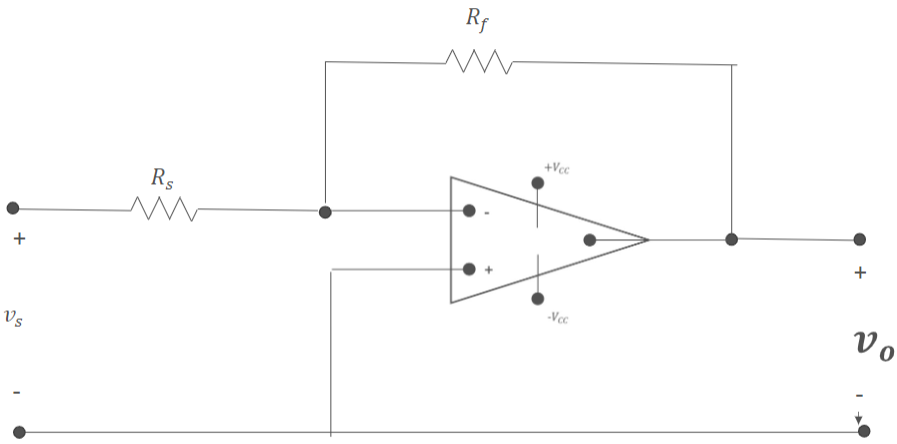

clc, clear, close all; 
Rf=1; Rs=1; vs=1;
 
v0=(-Rf/Rs)*vs

v0 = -1

## Non-inverting amplifier. $v_0 =v_s \left(1+\frac{R_f }{R_s }\right)$


$$v_0 \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Output}\;\mathrm{voltage}\ldotp \;\;\;\;\;\;\;v_s \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Source}\;\mathrm{voltage}\;\;\;\;\;\;\;\;\;\;R_f \left\lbrack \Omega \;\right\rbrack =\mathrm{Reference}\;\mathrm{resistor}\ldotp \;\;\;\;R_s \left\lbrack \Omega \;\right\rbrack =\mathrm{Resistor}$$


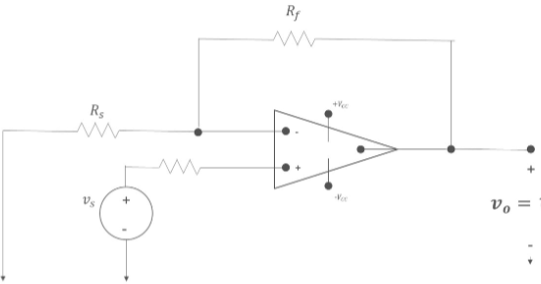

clc, clear, close all; 
Rf=1; Rs=1; vs=1;
 
v0=vs*(1+Rf/Rs)

v0 = 2

## Difference amplifier. $\mathrm{General}:v_0 =\frac{R_d \left(R_a +R_b \right)}{R_a \left(R_c +R_d \right)}v_b -\frac{R_b }{R_a }v_a \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{if}\;\frac{R_a }{R_b }=\frac{R_c }{R_d }:v_0 =\frac{R_b }{R_a }\left(v_b -v_a \right)\;\;$


$$v_0 \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Output}\;\mathrm{voltage}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;R_a ,\;R_b ,{\;R}_c ,{\;R}_d \;\left\lbrack \Omega \;\right\rbrack =\mathrm{Resistor}\;\;\;\;\;\;v_b -v_a \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Difference}\;\mathrm{in}\;\mathrm{voltage}\ldotp \;\;\;\;\;v_a ,v_b \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Input}\;\mathrm{voltage}\ldotp$$
  

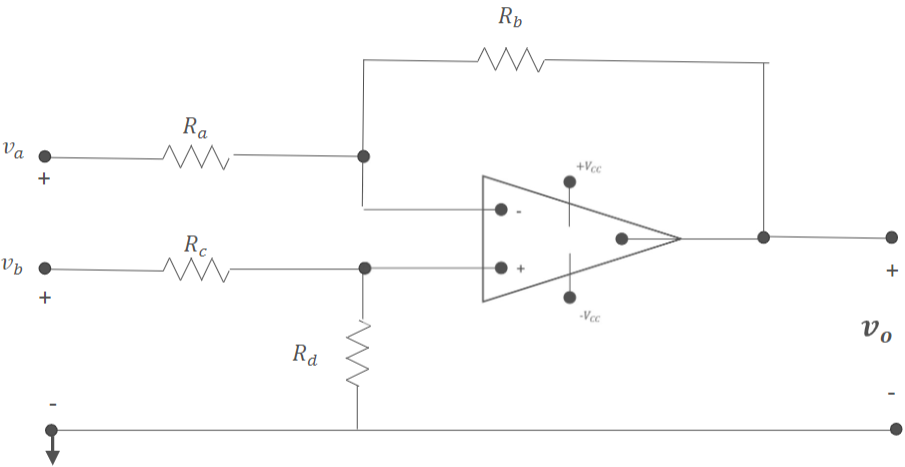

clc, clear, close all; 
Ra= 100;Rb=1000;Rc= 100;Rd=1;
va= 10.597e-3;vb= 1.612e-3;
metode="RaLikRb";
 
switch metode
case  "Generelt"
    v0=((Rd*(Ra+Rb))/(Ra*(Rc+Rd)))*vb-va(Rb/Ra)
case  'RaLikRb'
    v0=(Rb/Ra)*(vb-va)
end

v0 =                   -0.08985


### Resistance from amplification. $R_b =V_{\mathrm{forsterkning}} \cdot R_a$


$$\mathrm{Amplification}\left\lbrack \mathrm{Volt}\right\rbrack :\frac{R_b }{R_a }\;\;\;\;\;\;\;\;\;\;\;\;\;\;R_b \left\lbrack \Omega \;\right\rbrack =\mathrm{Amplification}\cdot R_{a\;} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;R_{c\;} \left\lbrack \Omega \;\right\rbrack =R_d \cdot \frac{R_a }{R_b }$$


clc, clear, close all;
syms Rb
forsterkning=400; Ra=100;Rd=10000;
Eq1=Rb==forsterkning*Ra;
 
Rb=solve(Eq1, Rb)

$$Rb = 40000$$

Rc=Rd*(Ra/Rb)

$$Rc = 25$$

## Summing amplifier. $\mathrm{General}:\;v_0 =-\left(\frac{R_f }{R_a }v_a +\frac{R_f }{R_b }v_b \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{if}\;R_a =R_b :v_0 =-\frac{R_f }{R_a }\left(v_a +v_b \right)$

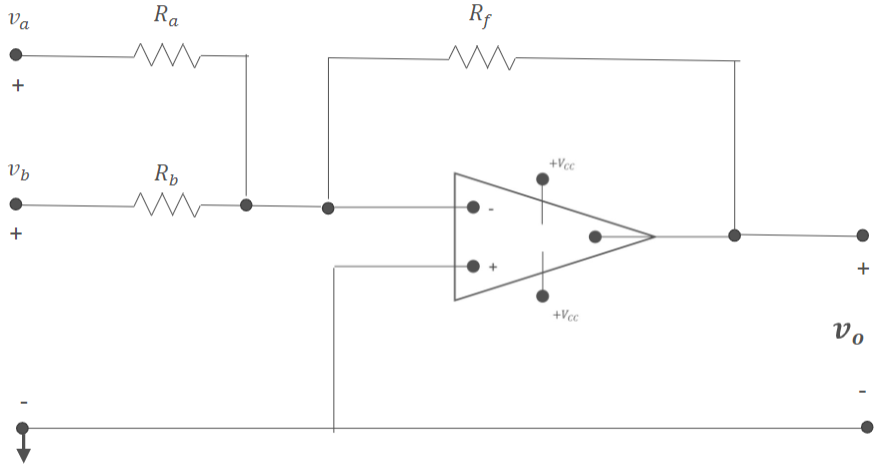


$$V_o \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Voltage}\;\mathrm{out}\ldotp$$



$$R_a ,R_b ,R_f \left\lbrack \Omega \;\right\rbrack =\mathrm{Resistance}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;V_a \;\mathrm{og}\;V_b \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{voltage}\;\mathrm{in}\ldotp$$


clc, clear, close all; 
Ra= 1;Rb= 1;Rf= 1;
va= 1;vb= 1;
metode="Generelt";
 
switch metode
    case  'Generelt'
        v0=-((Rf/Ra)*va+(Rf/Rb)*vb)
    case  'RaLikRb'
        v0=-Rf/Ra*(va+vb)
end

v0 =     -2


# Pt-element.

## Temperature as a function of resistance Rt. $T\left\lbrack ℃\right\rbrack =-A\pm \frac{\sqrt{\;A^2 -4B\left(1-R_T /R_0 \right)}}{2B}$


$$A\left\lbrack ℃^{-1} \right\rbrack ,B\left\lbrack ℃^{-2} \right\rbrack =\mathrm{van}-\mathrm{dusen}\;\mathrm{Coefficient}\ldotp \;\;\;\;R_T \left\lbrack \Omega \;\right\rbrack =\mathrm{Resistance}\;\mathrm{at}\;\mathrm{given}\;\mathrm{temp}\ldotp \;\;\;\;\;R_0 \left\lbrack \Omega \;\right\rbrack =\mathrm{element}\;\mathrm{type}\;\mathrm{dependant}\;\mathrm{resistance}\;\mathrm{at}\;\mathrm{temp}\;\;0℃\ldotp \left(\mathrm{pt100}:100\Omega \;\ldotp \;\mathrm{pt1000}:1000\Omega \;\right)$$


clc, clear, close all;  

R0= 23;A = 0.0039083;B = -5.775e-7;RT = 1143;
 
T = ((-A) + (sqrt(A^2 - (4*B) * (1-(RT/R0)))))/(2*B)

T =       3.383809523809524e+03 - 8.536469336464545e+03i

## Resistance at temperature T. $R_T =R_0 \left(1+\textrm{AT}+{\textrm{BT}}^2 \right)$


$$A\left\lbrack ℃^{-1} \right\rbrack ,B\left\lbrack ℃^{-2} \right\rbrack =\mathrm{van}-\mathrm{dusen}\;\mathrm{koeffisienter}\ldotp \;\;\;\;T\left\lbrack ℃\right\rbrack =\mathrm{Given}\;\mathrm{temperature}\;\;\;\;\;\;\;\;\;R_0 \left\lbrack \Omega \;\right\rbrack =\mathrm{element}\;\mathrm{type}\;\mathrm{dependant}\;\mathrm{resistance}\;\mathrm{at}\;\mathrm{temp}\ldotp \left(\mathrm{pt100}:100\Omega \;\ldotp \;\mathrm{pt1000}:1000\Omega \;\right)$$


clc, clear, close all;  

R0=100;A=0.0039083;B=-5.775e-7;T=1;
 

RT=R0*(1+A*T+B*T^2)

RT =               100.39077225


# Strain Gauge.


$$R=\rho \;\frac{l}{A}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{\Delta R}{R}=G\cdot e\approx G\cdot \frac{\Delta l}{\;l}$$
            
$$G=\textrm{Gauge}\textrm{factor}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;e=\textrm{strain}$$


typical Gauge has:

- Gauge factor 2.0 - 2.2

- Unstrained resistance: $120\pm 1\Omega \;$

- Linearity within $\pm \;0\ldotp 3%$

- Max tensile strain $\pm \;2\cdot {10}^{-2}$

- max compressive strain $+2\cdot {10}^{-2\;}$

- Max operating temp. $150$$\textrm{℃}$

clc, clear, close all;
p=13; l=0.2; A=3;
 

R =    4.333333333333333

R=p*(l/A)

## strain: $e=\frac{\Delta R}{\textrm{RG}}$


$$G=\mathrm{Gauge}\;\mathrm{faktor}\ldotp \;\;\;\;R\left\lbrack \Omega \;\right\rbrack =\mathrm{Gauge}\;\mathrm{resistanse}\;\left(\mathrm{unstretched}\right)\ldotp \;\;\;\;\;\;\;\Delta R\left\lbrack \Omega \;\right\rbrack =\mathrm{Resistance}\;\mathrm{when}\;\mathrm{stretched}\ldotp \;\;\;$$


clc, clear, close all;
deltaR=124.3-120;R=120; G=2.0;
 
e=(deltaR) / (G*R)

e = 0.0179

## Length stretched: $\Delta l\left\lbrack \textrm{cm}\right\rbrack =e\cdot l$


$$e=\mathrm{strain}\ldotp \;\;\;\;\;\;\;\;l\left\lbrack \mathrm{cm}\right\rbrack =\mathrm{Gauges}\;\mathrm{length}$$


clc, clear, close all;
l=8;e=0.0179;
 
Deltal=e*l

Deltal = 0.1432

## Resistance when stretched. $\Delta R\left\lbrack \Omega \;\right\rbrack =R\cdot G\cdot e$


$$R\left\lbrack \Omega \;\right\rbrack =\mathrm{Gauge}\;\mathrm{resistanse}\;\left(\mathrm{unstretched}\right)\ldotp \;\;\;\;\;\;G=\mathrm{Gauge}\;\mathrm{faktor}\ldotp \;\;\;\;\;e=\mathrm{Strain}$$


clc, clear, close all;
R=120; G=2; e=0.02;
DeltaR=R*G*e

DeltaR = 4.8000

# Potentiometer.    

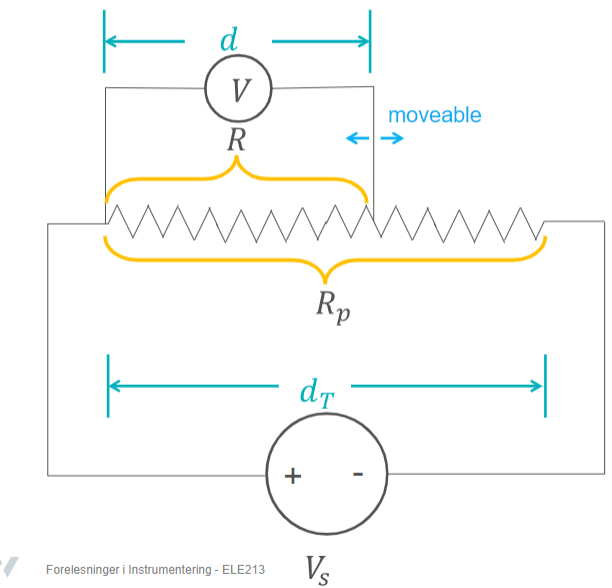

## Resistance. $R\left\lbrack \Omega \;\right\rbrack =\frac{d}{d_T }R_p \;$


$$d\left\lbrack m\right\rbrack =\mathrm{Resistor}\;\mathrm{displacement}\ldotp \;\;\;d_T \left\lbrack m\;\right\rbrack =\mathrm{Maximum}\;\mathrm{displacement}\ldotp \;\;\;\;\;{\;\;R}_p \left\lbrack \Omega \;\right\rbrack =\mathrm{Potentiometer}\;\mathrm{resistance}\left(\mathrm{fully}\;\mathrm{scaled}\right)\ldotp$$


clc, clear, close all;
Rp=250; d=0.00634; dt=0.02;
R=(d/dt)*Rp

R =   79.250000000000000

 
""

## Voltage. $V\left\lbrack \textrm{volt}\right\rbrack =\frac{d}{d_T }V_s$


$$d\left\lbrack m\right\rbrack =\mathrm{Resistor}\;\mathrm{displacement}\ldotp \;\;\;d_T \left\lbrack m\;\right\rbrack =\mathrm{Maximum}\;\mathrm{displacement}\ldotp \;\;V_s \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{source}\;\mathrm{voltage}\ldotp$$


clc, clear, close all;
Vs=1.5; d=0.001; dt=0.02;
V=(d/dt)*Vs

V = 0.0750

## Distance from resistance. $d\left\lbrack m\right\rbrack =\frac{R}{R_p }d_T$


$$R\left\lbrack \Omega \;\right\rbrack =\mathrm{Measured}\;\mathrm{resistance}\ldotp {\;\;R}_p \left\lbrack \Omega \;\right\rbrack =\mathrm{Potentiometer}\;\mathrm{resistancee}\left(\mathrm{fully}\;\mathrm{scaled}\right)\ldotp \;\;\;\;\;d_T \left\lbrack m\right\rbrack =\mathrm{Maximum}\;\mathrm{displacement}$$
    

clc, clear, close all;
R=67; Rp=250; dT=0.02;
d1=(R/Rp)*dT

d1 =    0.005360000000000

## Distance from voltage. $d\left\lbrack m\right\rbrack =\frac{V}{V_s }d_T$


$$d_T \left\lbrack m\right\rbrack =\mathrm{Maximum}\;\mathrm{displacement}\ldotp \;\;\;\;\;\;\;V\left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Measured}\;\mathrm{voltage}\ldotp \;\;\;\;{\;V}_s \left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Source}\;\mathrm{voltage}\ldotp \;\;\;\;$$


clc, clear, close all;

d2 =    0.020000000000000

dT=0.02;V=1;Vs=1;
 
d2=(V/Vs)*dT

# Capacitor.


$$\begin{array}{l}
\textrm{Permativity}\;\textrm{of}\;\textrm{free}\;\textrm{space}:\epsilon {\;}_{0\;} =8\ldotp 854\cdot {10}^{-12\;\;} C^{2\;} /\;{\textrm{Nm}}^{2\;} \\
\textrm{Relative}\;\textrm{permativity}:\epsilon_{r\;} \\
C\left\lbrack F\right\rbrack =\frac{\epsilon_0 \epsilon_r A\left\lbrack m^2 \right\rbrack }{d\left\lbrack m\right\rbrack }
\end{array}$$


## Variable plate separation. $C\left\lbrack F\right\rbrack =\frac{\epsilon_0 \epsilon_r A}{d+x}$


$$A\left\lbrack m^2 \right\rbrack =\mathrm{Capacitor}\;\mathrm{surface}\;\mathrm{area}\ldotp \;\;\;\;\;\;\;\;\;\;d\left\lbrack m\right\rbrack =\mathrm{Dis}\mathrm{tance}\;\mathrm{between}\;\mathrm{plates}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;x\left\lbrack m\right\rbrack =\mathrm{lenghtdisplacement}\;\mathrm{from}\;\mathrm{original}\;\mathrm{position}\ldotp$$



$$\epsilon {\;}_{0\;} =8\ldotp 854\cdot {10}^{-12\;\;} C^{2\;} /\;{\mathrm{Nm}}^{2\;} :\mathrm{Pe}\mathrm{rmativity}\;\mathrm{in}\;\mathrm{air}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\epsilon_{r\;} =\mathrm{Relativ}\;\mathrm{permativity}$$
      

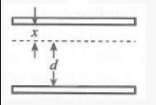   

clc, clear, close all;
e0 = 8.854*10^-12;  %elektrisk konstant:                    C^2/N*m^2.
er=1; d=2; A=3; x=4;
C=(e0*er*A)/(d+x)
 

## Varible effective area.$C\left\lbrack F\right\rbrack =\frac{{\textrm{𝜖}}_0 {\textrm{𝜖}}_r }{d}\left(A-\textrm{wx}\right)$


$$A\left\lbrack m^2 \right\rbrack =\mathrm{Capacitor}\;\mathrm{surface}\;\mathrm{area}\ldotp \ldotp \;\;\;\;\;\;\;\;\;\;d\left\lbrack m\right\rbrack =\mathrm{Dis}\mathrm{tance}\;\mathrm{between}\;\mathrm{plates}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;x\left\lbrack m\right\rbrack =\mathrm{lenght}\;\mathrm{displacement}\;\mathrm{from}\;\mathrm{original}\;\mathrm{position}\ldotp$$



$$w\left\lbrack m\right\rbrack =\mathrm{Width}\;\mathrm{displacement}\;\mathrm{from}\;\mathrm{original}\;\mathrm{position}\ldotp$$



$$\epsilon {\;}_{0\;} =8\ldotp 854\cdot {10}^{-12\;\;} C^{2\;} /\;{\mathrm{Nm}}^{2\;} :\mathrm{Pe}\mathrm{rmativity}\;\mathrm{in}\;\mathrm{air}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\epsilon_{r\;} =\mathrm{Relativ}\;\mathrm{permativity}$$
     

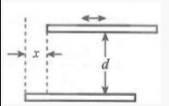

clc, clear, close all;
e0 = 8.854*10^-12;  %elektrisk konstant:                    C^2/N*m^2.
er=1; d=1; A=1; x=1;
w=1;

C =      0

C=(e0*er)/(d)*(A-w*x)
 

## Variable dielectric. $\left.C\left\lbrack F\right\rbrack =\frac{{\textrm{𝜖}}_0 w}{d}\left({\textrm{𝜖}}_2 l-{\left({\textrm{𝜖}}_2 -{\textrm{𝜖}}_1 \right)}x\right)$


$$\epsilon {\;}_{0\;} =8\ldotp 854\cdot {10}^{-12\;\;} C^{2\;} /\;{\mathrm{Nm}}^{2\;} :\mathrm{Permitivitet}\;in\;\mathrm{air}\ldotp \;\;\;\;d\left\lbrack m\right\rbrack =\mathrm{distance}\;\mathrm{between}\;\mathrm{plates}\ldotp \;\;\;\;l\left\lbrack m\right\rbrack =\mathrm{length}\;\mathrm{of}\;\mathrm{plates}\ldotp$$



$$\epsilon_1 {,\;\epsilon }_2 =\mathrm{Permitivity}\;\mathrm{in}\;\mathrm{dielectric}\;\mathrm{#1}\;\mathrm{og}\;\mathrm{#2}\ldotp \;\;\;x\left\lbrack m\right\rbrack =\mathrm{Length}\;\mathrm{displacement}\;\mathrm{from}\;\mathrm{original}\;\mathrm{position}\ldotp$$


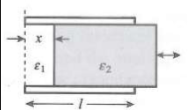

clc, clear, close all;
e0 = 8.854*10^-12;  %elektrisk konstant:                    C^2/N*m^2.
er=1; e1=1; e2=1;d=1;
A=1; x=1;w=1; l=1;
C=(e0*w)/(d)*(e2*l-(e2-e1)*x)

C = 8.8540e-12

## Liquid-level. $h_{liquid} =\frac{h_{total} }{C_{full} -C_{empty} }C_m -\frac{C_{empty} h_{total} }{C_{full} -C_{empty} }=kI+a$

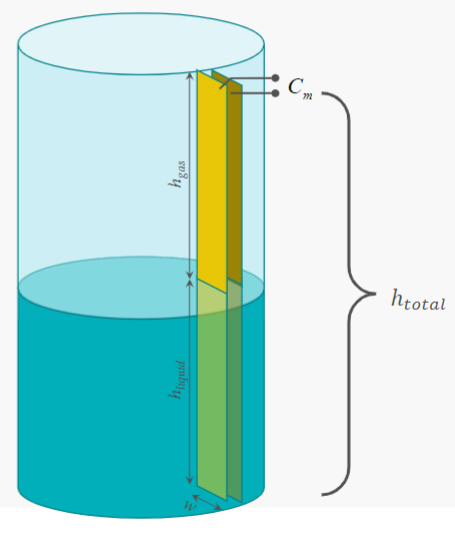


$$h\left\lbrack m\right\rbrack =\mathrm{height}\;\mathrm{of}\;\mathrm{container}\ldotp \;\;\;\;\;\;\;w\left\lbrack m\right\rbrack =\mathrm{width}\;\mathrm{of}\;\mathrm{capacitor}\ldotp \;\;\;\;\;\;d\left\lbrack m\right\rbrack =\mathrm{distance}\;\mathrm{between}\;\mathrm{capacitor}\;\mathrm{plates}\ldotp$$


clc, clear, close all;
d=0.004;w=0.03;h=1.2;
e=8.854e-12;

## Permitivity in Liquid. ${{\left({\textrm{𝜖}}_r \right|}}_{liquid} =C_{full} \frac{d}{{\textrm{𝜖}}_0 wh_{total} }$


$$C_{\mathrm{full}} \left\lbrack F\right\rbrack =\mathrm{Capacitance}\;\mathrm{at}\;\mathrm{full}\;\mathrm{tank}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\epsilon {\;}_{0\;} =8\ldotp 854\cdot {10}^{-12\;\;} C^{2\;} /\;{\mathrm{Nm}}^{2\;} :\mathrm{Permitivity}\;\mathrm{in}\;\mathrm{air}\ldotp \;\;\;$$



$$h\left\lbrack m\right\rbrack =\mathrm{Height}\;\mathrm{of}\;\mathrm{container}\ldotp \;\;\;\;\;\;\;w\left\lbrack m\right\rbrack =\mathrm{Width}\;\mathrm{capacitor}\ldotp \;\;\;\;\;\;d\left\lbrack m\right\rbrack =\mathrm{distance}\;\mathrm{between}\;\mathrm{capacitor}\;\mathrm{plates}\ldotp$$


Cfull=220e-12;
erliquid=Cfull*(d/(e*w*h))

erliquid = 2.7608

## permativity in gass.${{\left({\textrm{𝜖}}_r \right|}}_{gas} =C_{empty} \frac{d}{{\textrm{𝜖}}_0 wh_{total} }$


$$C_{\mathrm{empty}} \left\lbrack F\right\rbrack =\mathrm{Capacitance}\;\mathrm{at}\;\mathrm{empty}\;\mathrm{tank}\ldotp \;\;\;\;\;\;\;\;\;\;\epsilon {\;}_{0\;} =8\ldotp 854\cdot {10}^{-12\;\;} C^{2\;} /\;{\mathrm{Nm}}^{2\;} :\mathrm{Permitivity}\;\mathrm{in}\;\mathrm{air}\ldotp$$



$$h\left\lbrack m\right\rbrack =\mathrm{Height}\;\mathrm{of}\;\mathrm{container}\ldotp \;\;\;\;\;\;\;w\left\lbrack m\right\rbrack =\mathrm{Width}\;\mathrm{capacitor}\ldotp \;\;\;\;\;\;d\left\lbrack m\right\rbrack =\mathrm{distance}\;\mathrm{between}\;\mathrm{capacitor}\;\mathrm{plates}\ldotp$$


Cempty=80e-12;
ergass=Cempty*(d/(e*w*h))

ergass = 1.0039


%Cm=((e*erliquid*w*h)/d)+((e*ergass*w*h)/d)
Cm=140e-12;
 


$$h_{liquid} =\frac{h_{total} }{C_{full} -C_{empty} }C_m -\frac{C_{empty} h_{total} }{C_{full} -C_{empty} }=kI+a$$



$$h_{\mathrm{total}} \left\lbrack m\right\rbrack =\mathrm{Heigth}\ldotp \;\;\;\;C_{\mathrm{empty}} \left\lbrack F\right\rbrack =\mathrm{Capacitance}\;\mathrm{at}\;\mathrm{empty}\;\mathrm{tank}\ldotp \;\;\;\;\;\;\;C_{\mathrm{full}} \left\lbrack F\right\rbrack =\mathrm{Capacitance}\;\mathrm{at}\;\mathrm{full}\;\mathrm{tank}\ldotp \;\;\;\;\;C_m \left\lbrack F\right\rbrack =\mathrm{capacitance}\;\mathrm{at}\;\mathrm{level}\;m\ldotp$$


hliquid=((h/(Cfull-Cempty))*Cm-((Cempty*h)/(Cfull-Cempty)))

hliquid = 0.5143

# Thick film polymer.

## Resistance. $R_T =R_0 \cdot \left(1+\alpha \;T\right)$

clc, clear, close all;
R0=2; alpha=2; T=3;
RT=R0*(1+alpha*T)

RT =     14

# pizoelectric-element.

# Hall-effect sensor.

## Magnetic field. $V\left\lbrack V\right\rbrack =\frac{R_H \textrm{IB}}{\;t}$


$$R_{H\;} \left\lbrack m^3 /C\right\rbrack =\mathrm{Hall}\;\mathrm{Coefficient}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;t\left\lbrack m\right\rbrack =\mathrm{Thickness}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;B\left\lbrack \mathrm{Tesla}\right\rbrack =\mathrm{magnetic}\;\mathrm{field}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;I\left\lbrack \mathrm{Amp}\ae r\right\rbrack =\mathrm{Current}$$



$$n=\mathrm{Elektron}\;\mathrm{density}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;e=\mathrm{Elektron}\;\mathrm{charge}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;p=\mathrm{density}\;\mathrm{of}\;\mathrm{holes}$$


clc, clear, close all;
RH=0.02; Ts=0.5e-3; B=0.2; I=7.5e-3;
 
V=(RH*I*B)/Ts

V = 0.0600

## Field strenght from voltage. $B=\frac{\textrm{Vt}}{R_H I}$


$$B\left\lbrack \mathrm{Tesla}\right\rbrack =\mathrm{Magnetic}\;\mathrm{field}$$



$$V\left\lbrack \mathrm{Volt}\right\rbrack =\mathrm{Voltage}\ldotp \;\;\;\;\;\;R_{H\;} \left\lbrack m^3 /C\right\rbrack =\mathrm{Hall}\;\mathrm{Coefficient}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;t\left\lbrack m\right\rbrack =\mathrm{Thickness}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;I\left\lbrack \mathrm{Amp}\ae r\right\rbrack =\mathrm{Curren}t$$


clc, close all, clearvars  -except t RH I
V=100e-3;
 
feltstyrke=(V*Ts)/(RH*I)

feltstyrke = 0.3333

# Flow

## Mass from volum and mass density. $M=\rho V$


$$M\left\lbrack \mathrm{kg}\right\rbrack =\mathrm{Mass}$$



$$\rho \left\lbrack \mathrm{kg}/m^3 \right\rbrack =\mathrm{Mass}\;\mathrm{density}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;V\left\lbrack m^3 \right\rbrack =\mathrm{Volum}$$


clc, clear, close all;
rho=850; V=10;
 
Masse=rho*V

Masse = 9100

## Volum from mass and mass density. $V=\frac{M}{\rho \;}$


$$V\left\lbrack m^{3\;} \right\rbrack =\mathrm{Volum}\;\mathrm{in}\;\mathrm{cubic}\;\mathrm{meters}$$



$$M\left\lbrack \mathrm{kg}\right\rbrack =\mathrm{Mass}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\rho \;\left\lbrack \mathrm{kg}/m^3 \right\rbrack =M\;\mathrm{ass}\;\mathrm{density}\;\;\;\;\;$$


clc, clear, close all;
rho=850; M=109.09;
 
Volum=M/rho

Volum = 0.1283

## Mass flow rate. $q_m =\frac{M}{T}$


$$q_m \left\lbrack \mathrm{kg}/s\right\rbrack =\mathrm{Mass}\;\mathrm{flow}\;\mathrm{rate}\ldotp$$



$$T\left\lbrack \mathrm{sek}\right\rbrack =\mathrm{Time}\;\mathrm{mass}\;\mathrm{uses}\;\mathrm{through}\;\mathrm{measuring}\;\mathrm{device}\ldotp \;\;\;\;\;\;\;\;\;\;M\left\lbrack \mathrm{kg}\right\rbrack =\mathrm{Mass}$$


clc, clear, close all;
M=9100; T= 63;
 
stromningsrate=M/T

stromningsrate = 144.4444

## Volumetric flow rate. $q_V =\frac{q_m }{\rho \;}$


$$q_V \left\lbrack m^{3\;} /s\right\rbrack =\mathrm{Volumetric}\;\mathrm{flow}\;\mathrm{rate}\ldotp$$



$$\rho \left\lbrack \mathrm{kg}/m^3 \right\rbrack =\mathrm{Mass}\;\mathrm{density}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;q_m \left\lbrack \mathrm{kg}/s\right\rbrack =\mathrm{Mass}\;\mathrm{flow}\;\mathrm{rate}\;\;\;\;$$


clc, clear, close all;
qm=144.444; rho=910;
 
qv=qm/rho

qv = 0.1587

## Volumetric flow rate from flow rate. $q_v \left\lbrack m^3 /s\right\rbrack =\frac{\pi \;d^2 \left\lbrack m\right\rbrack \;}{4}\cdot v\left\lbrack m/s\right\rbrack$


$$q_v \left\lbrack m^3 /s\right\rbrack =\mathrm{Volumetric}\;\mathrm{flow}\;\mathrm{rate}\ldotp$$



$$d\left\lbrack m\right\rbrack =\mathrm{Distance}\;\mathrm{in}\;\mathrm{meters}\ldotp \;\;\;\;\;\;v\left\lbrack m/s\right\rbrack =\mathrm{Flow}\;\mathrm{rate}\ldotp$$


clc, clear, close all;
d=0.25; v=20.2;
 
qv=((pi*d^2)/4)*v

qv = 0.9916

## Average flow rate. $v=\frac{4q_v }{\pi \;d^2 }$


$$\;v\left\lbrack m/s\right\rbrack =\mathrm{Average}\;\mathrm{flow}\;\mathrm{rate}\ldotp$$



$$d\left\lbrack \mathrm{meter}\right\rbrack =\mathrm{dinsance}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;q_v \left\lbrack m^{3\;} /s\right\rbrack =\mathrm{Volumetric}\;\mathrm{flow}\;\mathrm{rate}\ldotp \;\;\;\;\;$$


clc, clear, close all;
qv=2; d=0.15;
 
v=(4*qv)/(pi*d^2)

v = 113.1768

# Ultrasonic.

## Flow rate. $v=\frac{L\left(t_1 -t_2 \right)}{2t_1 t_2 \cos \phi \;\;}$


$$v\left\lbrack m/s\right\rbrack =\mathrm{Flow}\;\mathrm{rate}\ldotp$$



$${\;t}_1 \;\left\lbrack s\right\rbrack \mathrm{og}\;t_2 \left\lbrack s\right\rbrack =\mathrm{transit}\;\mathrm{times}\;\mathrm{in}\;\mathrm{seconds}\;\;\;\;\;\;\;\;\;\;\;L\left\lbrack m\right\rbrack =\mathrm{sound}\;\mathrm{path}\;\mathrm{ength}\;\mathrm{in}\;\mathrm{meters}\ldotp \;\;\;\;\;\;\;\;\phi \;\left\lbrack {\mathrm{degrees}}^{\circ \;} \right\rbrack =\mathrm{angle}\;\mathrm{between}\;\mathrm{sound}\;\mathrm{path}\;\mathrm{and}\;\mathrm{pipes}\;\mathrm{axial}\;\mathrm{direction}\ldotp$$


clc, clear, close all;
L=0.3 ;t1=750e-6; t2=700e-6; phi=pi/4;
 
v=( ( L*(t1-t2) ) / (2*t1*t2*cos(phi) ) )

v = 20.2031

## speed of sound. $C=\frac{L\left(t_1 +t_2 \right)}{2t_1 t_2 }$


$$C\left\lbrack m/s\right\rbrack =\mathrm{speed}\;\mathrm{of}\;\mathrm{sound}\ldotp$$



$$t_1 \;\left\lbrack s\right\rbrack \mathrm{og}\;t_2 \left\lbrack s\right\rbrack =\mathrm{transit}\;\mathrm{times}\;\mathrm{in}\;\mathrm{seconds}\ldotp \;\;\;\;L\left\lbrack m\right\rbrack =\mathrm{sound}\;\mathrm{path}\;\mathrm{ength}\;\mathrm{in}\;\mathrm{meters}\ldotp$$


clc, clear, close all;
L=0.3 ;t1=750e-6; t2=700e-6;
 
C=( ( L*(t1+t2) ) / (2*t1*t2) )

C = 414.2857

## Level measuring. $H=\frac{\textrm{ct}}{2}$


$$H\left\lbrack m\right\rbrack =\mathrm{distance}\;\mathrm{from}\;\mathrm{emawsuring}\;\mathrm{device}\ldotp$$



$$c\left\lbrack m/s\right\rbrack =\;\mathrm{speed}\;\mathrm{of}\;\mathrm{sound}\;\mathrm{in}\;\mathrm{gas},\;\mathrm{typical}:\;\;330-400m/s\ldotp \;\;\;\;\;\;\;t\left\lbrack s\right\rbrack =\mathrm{time}\;\mathrm{of}\;\mathrm{flight}\ldotp$$


clc, clear, close all;
c=340; Ts=7.4e-3;
 
Level= (c*Ts)/2

Level =                      1.258


# Pressure.


$$p=p_0 +\rho \textrm{gh}$$



$$\rho \left\lbrack \mathrm{kg}/m^3 \right\rbrack =\mathrm{Mass}\;\mathrm{density}\ldotp \;\;\;\;\;\;\;g\left\lbrack m/s^2 \right\rbrack =\mathrm{gravitational}\;\mathrm{acceleration}\ldotp \ldotp \;\;\;\;\;\;\;h\left\lbrack m\right\rbrack =\mathrm{height}\ldotp$$


## Level from pressure differance. $h_i \left\lbrack m\right\rbrack =\frac{p_1 -p_2 +{\rho \;}_1 {\mathrm{gh}}_1 -{\rho \;}_2 {\mathrm{gh}}_2 }{\left(\rho_1 -\rho {\;}_2 \right)g}$


$$\begin{array}{l}
\rho_1 \left\lbrack \mathrm{kg}/m^3 \right\rbrack \;={\mathrm{substance}}_1 -\mathrm{density}\ldotp \;\;\;\;\;\;\rho_2 \left\lbrack \mathrm{kg}/m^3 \right\rbrack ={\mathrm{substance}}_2 -\mathrm{density}\ldotp \;\;\;\;\;\;\;\;h_1 \left\lbrack m\right\rbrack ={\mathrm{Substance}}_1 -\mathrm{level}\ldotp \;\;\;\;\;\;\;\;\;\;h_2 \left\lbrack m\right\rbrack ={\mathrm{substance}}_2 -\mathrm{level}\ldotp \\
g\left\lbrack m/s^2 \right\rbrack =\mathrm{gravitatnonal}\;\mathrm{acceleration}\ldotp \;\;\;p_1 \left\lbrack \mathrm{Pa}\right\rbrack =\mathrm{Pressure}\;1\ldotp \;\;\;\;\;\;\;\;p_2 \left\lbrack \mathrm{Pa}\right\rbrack =\mathrm{pressure}\;2\ldotp \;\;\;\;\;\;\;\;\;\;\;\Delta \;P\left\lbrack \mathrm{Pa}\right\rbrack =p_1 -p_2 =\mathrm{Difference}\;\mathrm{in}\;\mathrm{pressure}\ldotp 
\end{array}$$


clc, clear, close all;
g=9.81;
trykkforskjell=7500; tetthet1=1000; tetthet2=1.2;
h1=0.05; h2=1.4;

 
Level=( trykkforskjell + (tetthet1*g*h1) - (tetthet2*g*h2) ) / ( (tetthet1-tetthet2)*g )

Level = 0.8138

# signal.

## dB from amplitude. $dB=20\log {\left(\frac{A\left\lbrack V\right\rbrack }{A_0 \left\lbrack V\right\rbrack }\right)}$


$$A=\mathrm{Signal}\;\mathrm{amplitude}\ldotp \;\;\;\;\;\;\;\;\;\;\;A_0 =\mathrm{Reference}\;\mathrm{signal}\;\mathrm{amplitude}\ldotp$$


clc, clear, close all;
A=0.0666; A0=2;
 
dB=20*log10(A/A0)

dB = -29.5511

## Amplitude from dB. $A\left\lbrack V\right\rbrack =A_0 \left\lbrack V\right\rbrack \cdot {10}^{\frac{dB}{20}}$


$$A=\mathrm{Signal}\;\mathrm{amplitude}\ldotp \;\;\;\;\;\;\;\;\;\;\;A_0 =\mathrm{Reference}\;\mathrm{signal}\;\mathrm{amplitude}\ldotp$$


clc, clear, close all;
A0=2; dB=-32;
 
A=A0*10^(dB/20)

A = 0.1507

## Signal after filtration. $x{\left(t\right)}=A\cdot \cos {\left(\textrm{𝜔}t\right)}V\ldotp \;\;\;\;\;\;\;\;\;\;\;y{\left(t\right)}=A{\left|H{\left(\textrm{𝜔}\right)}\right|}\cdot \cos \left(\textrm{𝜔}t+\textrm{𝜙}+\angle H\left(\textrm{𝜔}\right)\right)$


$$\omega \;\left\lbrack \mathrm{rad}/\sec \right\rbrack =\mathrm{signal}-\mathrm{frequency}\ldotp \;\;\;\;\;\;\;\;\;$$


clc, clear, close all;


# Filter.

### RLC calculations: ${\textrm{𝜔}}_c =\frac{1}{\sqrt{LC}\;},\;\;\textrm{𝜁}=\frac{{\textrm{𝜔}}_0 RC}{2}$


$$R\left\lbrack \Omega \;\right\rbrack =\mathrm{Resistor}\ldotp \;\;\;\;\;\;\;\;C\left\lbrack F\right\rbrack =\mathrm{capacitor}\ldotp \;\;\;\;\;\;\;\;\;\;L\left\lbrack H\right\rbrack =\mathrm{inductor}\ldotp \;\;\;\;\;\;\;\;\zeta =\mathrm{attenuation}\;\mathrm{factor}\ldotp \;\;\;\;\;\;\;\;\omega {\;}_c \left\lbrack \mathrm{rad}/\sec \right\rbrack =\mathrm{break}\;\mathrm{frequency}\ldotp$$


R= 1; C= 1; L= 1; wc= 5000; zeta = 1;

C =      4.000000000000000e-05


####  Capacitor:$C\left\lbrack F\right\rbrack =\frac{2\textrm{𝜁}}{{\textrm{𝜔}}_0 R}$

C = (2*zeta)/(wc*R)

L = 1.0000e-03

####   Inductor:$L\left\lbrack H\right\rbrack =\frac{1}{{\textrm{𝜔}}_0^2 C}$

L = 1/(wc^2*C)

R = 10

#### Resistor: $R\left\lbrack \Omega \;\right\rbrack =\frac{2\textrm{𝜁}}{{\textrm{𝜔}}_c C}$

R = (2*zeta)/(wc*C)

wc =      1.581138830084190e+02


#### Break frequency: ${\textrm{𝜔}}_c =\frac{1}{\sqrt{LC}\ }$

wc= 1/(sqrt(L*C))

zeta =    0.100000000000000


#### Attenuation factor: $\textrm{𝜁}=\frac{{\textrm{𝜔}}_0 RC}{2}$

zeta = (knekkfrekvens*R*C)/2

## First-order low pass-filter. $|H\left(\omega \;\right)|=\frac{1}{\sqrt{1+{\left(\omega \;/\omega_c \right)}^2 \;}},\;\;\;\;\;\angle \;H\left(\omega \;\right)=-\tan^{-1} \left(\omega \;/\omega_c \right)$

 
$${\omega \;}_c \left\lbrack \mathrm{rad}/\sec \right\rbrack =\mathrm{Break}\;\mathrm{frequency}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\omega \;\left\lbrack \mathrm{rad}/\mathrm{sek}\right\rbrack =\mathrm{signal}-\mathrm{frequency}$$


clc, clear, close all;
knekkfrekvens=0.5; frekvens=300;
 
h=1/(sqrt(1+(frekvens/knekkfrekvens)^2));

H = 0.0017

H=abs(h)

radH = -1.5691

radH=-atan(frekvens/knekkfrekvens)

vinkelH = 0.0955

vinkelH=rad2deg(H)

x =     1.5903    2.3464    2.4409    2.4216    2.6518    2.8900    2.9436    2.9908    3.1297    3.2100    3.1832    3.1727    3.1894    3.1341    3.0201    2.9274    2.8310    2.6765    2.5015    2.3490    2.1856    1.9913    1.8059    1.6447    1.4804    1.3141    1.1758    1.0640    0.9621    0.8793    0.8322    0.8121    0.8110    0.8375    0.8965    0.9782    1.0790    1.2030    1.3477    1.5048    1.6719    1.8485    2.0292    2.2080    2.3823    2.5491    2.7035    2.8421    2.9620    3.0607


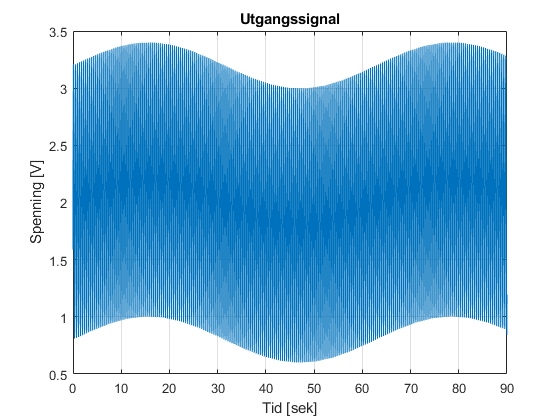

clc, clear, close all;
filtertype = "Lavpass";

Ts = 62.8;                     %Sampling periode.
N = 90;                        %Antal samples.
t = (0:0.01:N);                %Sampling punkt.

knekkfrekvens = 0.5;
f1 = 0.1;                   %frekvens 1
f2 = 15;                    %frekvens 2
f3 = 300;                   %frekvens 3
amp0 = 2;                   %amplitude til konstant-leddet
amp1 = 0.2;                 %amplitude til f1
amp2 = 1.2;                 %amplitude til f1
amp3 = 1;                   %amplitude til f1

signal = amp0 + amp1*sin(f1*t) + amp2*sin(f2*t) + amp3*sin(f3*t);

switch filtertype
    case 'Lavpass'

    x = lowpass(signal,knekkfrekvens)
        figure('Name','Utgangssignal')
        plot(t,x)
        title('Utgangssignal')
        xlabel('Tid [sek]')
        ylabel('Spenning [V]')
        grid on;
        set(gcf,'Visible','on');

    case 'Høypass'

    x = highpass(signal,knekkfrekvens);
        figure('Name','Utgangssignal')
        plot(t,signal)
        title('Utgangssignal')
        xlabel('Tid [sek]')
        ylabel('Spenning [V]')
        grid on;
        set(gcf,'Visible','on');

    case'Bandpass'
end

## Second-order low pass-filter. ${\left|H{\left(\textrm{𝜔}\right)}\right|}=\frac{1}{\sqrt{1+{{\left({\textrm{𝜔}}^2 /{\textrm{𝜔}}_c^2 \right)}}^2 +{{\left(2\textrm{𝜁}\textrm{𝜔}/{\textrm{𝜔}}_c \right)}}^2 }}$$\angle H{\left(\textrm{𝜔}\right)}={\left\{\begin{array}{c}
-\tan^{-1} {\left(\frac{2\textrm{𝜁}\textrm{𝜔}/{\textrm{𝜔}}_c }{1-{\textrm{𝜔}}^2 /{\textrm{𝜔}}_c }\right)},\ \ \textrm{𝜔}<{\textrm{𝜔}}_c \\
-\textrm{𝜋}-\tan^{-1} {\left(\frac{2\textrm{𝜁}\textrm{𝜔}/{\textrm{𝜔}}_c }{1-{\textrm{𝜔}}^2 /{\textrm{𝜔}}_c }\right)},\ \ \textrm{𝜔}>{\textrm{𝜔}}_c 
\end{array}\right)}$

clc, clear, close all;
knekkfrekvens=5000; frekvens=2000; zeta = 1;
 

h = 1 / (sqrt(1 + ((frekvens^2)/(knekkfrekvens^2))^2 + ((2*zeta*frekvens)/knekkfrekvens)^2 ))

h =          0.774844659217179


H = abs(h)

H =          0.774844659217179


rad_H = -atan( ((2*zeta*frekvens)/(knekkfrekvens)) / ( 1 - ((frekvens)^2/(knekkfrekvens^2)) ) )

rad_H =          -0.76101275422473


vinkel_H = rad2deg(rad_H); 